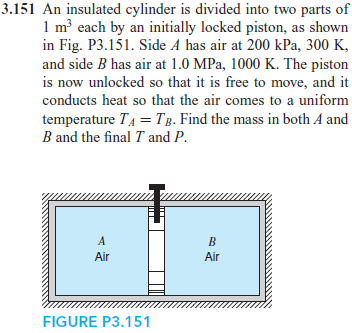

# symbolic units class

u = symunit;
air = ig;
old_assum = assumptions;
clearassum;

# state 1

% ---------------
% Side A
pa1 = 200*u.kPa;
Vola1 = 1*u.m^3;
Ta1 = 300*u.K;
ma = rewrite(pa1*Vola1/(air.R*Ta1), u.kg);
ma_vpa = vpa(ma)

$$ma\_vpa = 2.3228803716608594657375145180023\,\mathrm{kg}$$

% ---------------
% Side B
pb1 = 1.0*u.MPa;
Volb1 = Vola1;
Tb1 = 1000*u.K;
mb = rewrite(pb1*Volb1/(air.R*Tb1), u.kg);
mb_vpa = vpa(mb)

$$mb\_vpa = 3.4843205574912891986062717770035\,\mathrm{kg}$$

% ---------------

# state 2

% ---------------
% Side A
pa2 = sym('pa2', 'positive');
Vola2 = sym('Vola2', 'positive');
Ta2 = sym('Ta2', 'positive');
% ---------------
% Side B
pb2 = sym('pb2', 'positive');
Volb2 = sym('Volb2', 'positive');
Tb2 = sym('Tb2', 'positive');
% ---------------

# work done

Wa_12(pa2, Vola2) = (pa1+pa2)*(Vola2-Vola1)/2;
Wb_12(pb2, Volb2) = (pb1+pb2)*(Volb2-Volb1)/2;

# heat transfer

Qa_12(pa2, Vola2, Ta2) = ma*air.cv*(Ta2-Ta1)+formula(Wa_12);
Qb_12(pb2, Volb2, Tb2) = mb*air.cv*(Tb2-Tb1)+formula(Wb_12);

# solution

% ---------------
eqn = sym.zeros(6,1);
eqn(1) = formula(Qa_12)+formula(Qb_12) == 0;
eqn(2) = formula(Wa_12)+formula(Wb_12) == 0;
eqn(3) = pa2 == pb2;
eqn(4) = Ta2 == Tb2;
eqn(5) = pa2*Vola2 == ma*air.R*Ta2;
eqn(6) = pb2*Volb2 == mb*air.R*Tb2;
% ---------------
[pa2 Vola2 Ta2 pb2 Volb2 Tb2] = solve(eqn, [pa2 Vola2 Ta2 pb2 Volb2 Tb2]); %#ok
pa2 = rewrite(simplify(pa2), u.kPa);
Vola2 = simplify(Vola2);
pb2 = rewrite(simplify(pb2), u.kPa);
Volb2 = simplify(Volb2);
% ---------------
pa2_vpa = vpa(pa2) %#ok

$$pa2\_vpa = 638.74877690685247996280980707922\,\mathrm{kPa}$$

Vola2_vpa = vpa(Vola2) %#ok

$$Vola2\_vpa = 0.75146914930217938819154094950497\,m^{3}$$

Ta2_vpa = vpa(Ta2) %#ok

$$Ta2\_vpa = 720.0\,K$$

pb2_vpa = vpa(pb2) %#ok

$$pb2\_vpa = 638.74877690685247996280980707922\,\mathrm{kPa}$$

Volb2_vpa = vpa(Volb2) %#ok

$$Volb2\_vpa = 1.1272037239532690822873114242575\,m^{3}$$

Tb2_vpa = vpa(Tb2) %#ok

$$Tb2\_vpa = 720.0\,K$$

% ---------------
clear pa2_vpa Vola2_vpa Ta2_vpa pb2_vpa Volb2_vpa Tb2_vpa
setassum(old_assum, 'clear');
% ---------------